clearvars;
load lombardgrid_paired/corpusCleaned.mat
load lombardgrid_paired/alignments_fixed.mat


savefolder = 'p2p_STfilter';
savefile = 'result';
frameLength = 0.02;
overlap = 0.5;
method = 6;


tic
    p2pModificationUV_V(corpusCleaned, alignments, frameLength, overlap, savefolder, savefile, method);

   100

   200

   300

   400

   500

   600

   700

   800

   900

        1000

        1100

        1200

        1300

        1400

        1500

        1600

        1700

        1800

        1900

        2000

        2100

        2200

        2300

        2400

        2500



toc

Elapsed time is 2552.315406 seconds.


savefolder = 'p2p_LPC_1';
savefile = 'result';

tic
    p2pModificationUV_V(corpusCleaned, alignments, frameLength, overlap, savefolder, savefile, method, 'lpc');

toc

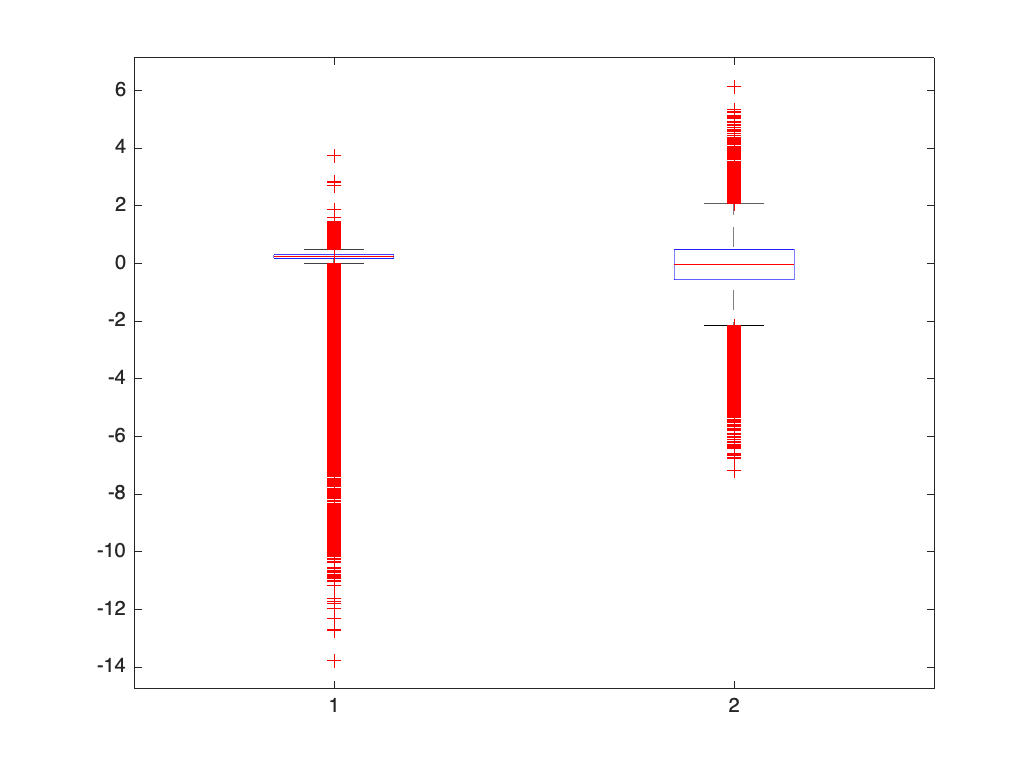

clearvars;
load p2p_STfilter/result.mat
abserr_p2p_ST = result.abserr_frame;

load p2p_LPC/result.mat

abserr_p2p_LPC = result.abserr_frame;

figure;
boxplot([abserr_p2p_ST,abserr_p2p_LPC])

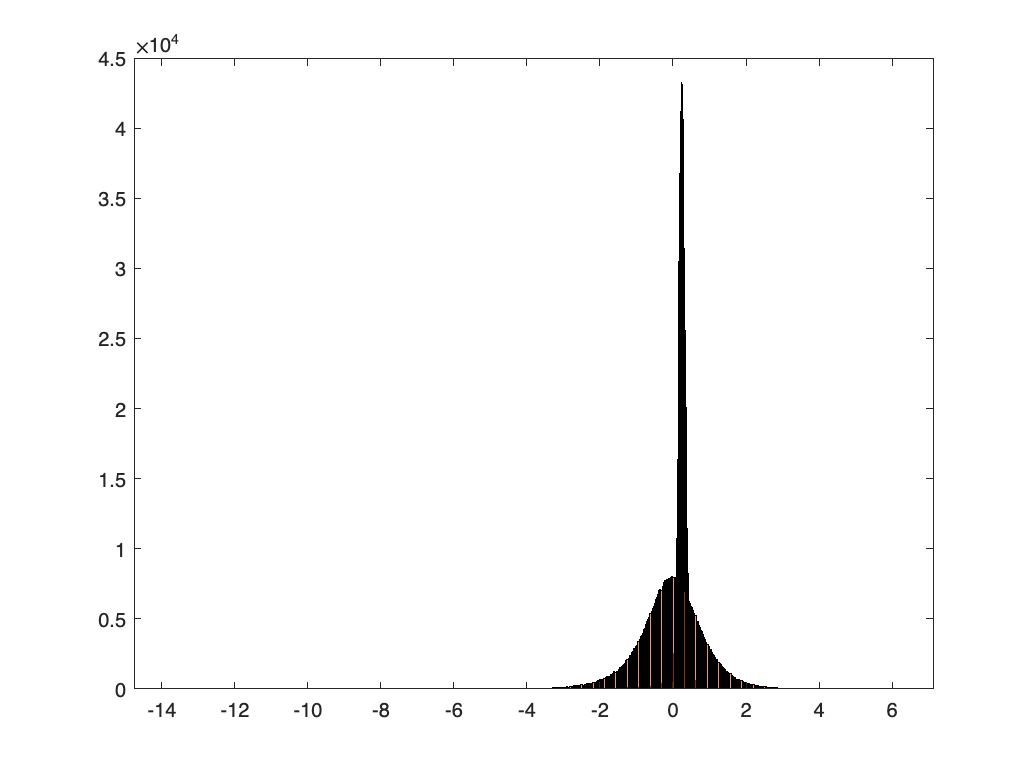


figure;
histogram(abserr_p2p_ST)
hold on
histogram(abserr_p2p_LPC)
hold off;


fprintf('mean:%.5f sigma:%.5f',mean(abserr_p2p_ST),std(abserr_p2p_ST))

mean:0.19789 sigma:0.43146


fprintf('mean:%.5f sigma:%.5f',mean(abserr_p2p_LPC),std(abserr_p2p_LPC))

mean:-0.05686 sigma:0.90740